# Interface Métodos Numéricos para ED/PVI

## 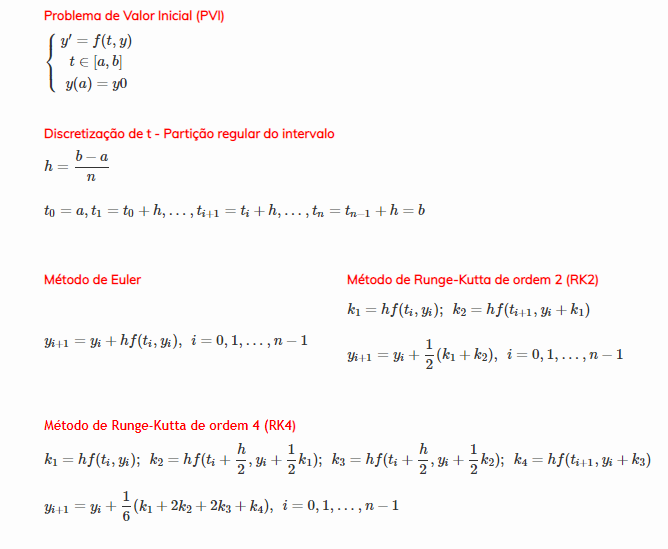

26/03/2021     Arménio Correia     armenioc@isec.pt

clear
syms y(t)

while 1
    %strF = input("f(t,y) = ","s");
    strF = "-2*t*y";
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

while 1
    a = 1;
    if (isscalar(a) && isreal(a)) 
        break
    end
end

while 1
    b = 1.5;
    if (isscalar(b) && isreal(b) && b>a) 
        break
    end
end
n = 20;
y0 = 2;

yEuler = NEuler(f,a,b,n,y0);

'NEuler' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Paulo Oliveira Ruivo\Downloads\armenio teste
    C:\Users\Paulo Oliveira Ruivo\Desktop\ttttttt\Trabalho Am2
    C:\Users\Paulo Oliveira Ruivo\Desktop\AM2\Aulas praticas\Aula 07
    C:\Users\Paulo Oliveira Ruivo\Desktop\AM2\Aulas praticas\Aula  09
    G:\O meu disco\Trabalho Am2

Change the MATLAB current folder or add its folder to the MATLAB path.

yRK2 = NRK2(f,a,b,n,y0);

sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
fplot(sExata,[a,b]);

g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroEuler = abs(yExata-yEuler);
erroRK2 = abs(yExata-yRK2);
tabela = [t.',yExata.',yEuler.',yRK2.',erroEuler.',erroRK2.']
array2table(tabela,"VariableNames",{'t','Exata','Euler','RK2','erroEuler','erroRK2'})

plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
plot(t,yRK2,"-b+")
hold off
grid on
legend('Exata','Euler','RK2')

 
